clear variables; close all; clc;

## Assignment: 

Like humans, Neanderthals had not only nuclear DNA, but also mitochondrial DNA in all their cells.  Like humans, the mitochondria of neanderthals contained 13 coding genes and 24 non-coding genes. The neanderthal mitochondrial genome has accession number 'NC_011137'.

- How does the number of genes stated above compare with the number of ORFs you find – explain your result. 

- Using what you have learnt above explore the neanderthal mitochondrial genome and find at least one *interesting* feature. Explain what you have found and what makes it interesting.

Make a new livescript with your working and explanations for this part and submit this file to the assignment on canvas.

Make sure to explain what you want to do, then put the code that does it, then finalise each section with an explanation of what you see in the results (for instance how do you interpret the plot, or the numbers you obtained).  Repeat this pattern for each major step/result in your report.  

## PART 1

## Load data

Load Neanderthals mitochondrial genome sequence.

neanderthal = getgenbank('NC_011137', 'SequenceOnly',true);
len = length(neanderthal);          % length of sequence string

## Find ORFs

Use command seqshoworfs to extract ORFs from all reading frames.

In this case I have used frames 1 2 3 and then the same for the sequence reversed (-1 -2 -3)  *inverse order*

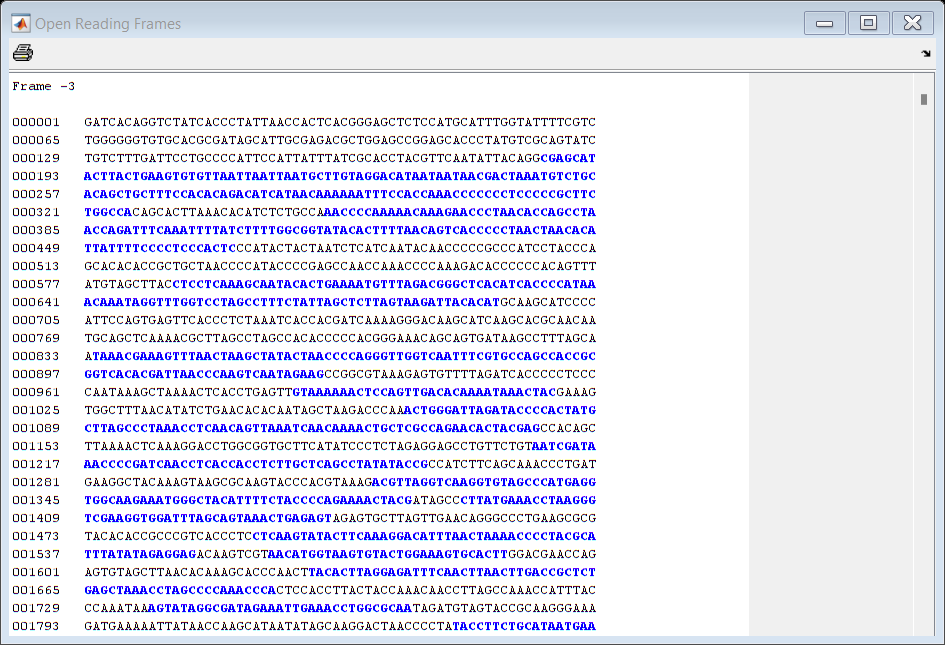

fs = 1×6 struct array with fields:
    Start
    Stop


fs = seqshoworfs(neanderthal, 'frames', [-3 -2 -1 1 2 3], 'ALTERNATIVESTARTCODONS',true)

For each frame now I analize the length of the ORFs, subtracting each ending index to the corresponding starting index (for frame 3 there is one stop index less than # start index, hence I don't consider that one *incomplete?* sequence)

l1 = fs(1).Stop-fs(1).Start ;
l2 = fs(2).Stop-fs(2).Start ;
l3 = fs(3).Stop-fs(3).Start(1:end-1) ;
l4 = fs(4).Stop-fs(4).Start ;
l5 = fs(5).Stop-fs(5).Start ;
l6 = fs(6).Stop-fs(6).Start ;

l6 =    141   117   105    93    33    81    51    69    48    57    30    60    33    42    42    33    75    36    33    75   132    60   114    72   204   387   159    90   138   120    42    48    63    33    30    33    57    42    36    30    69    60    30    30    72    30    72    36   183   321


Plot all length frequencies with histograms and display them together with mean length value for each frame. (not needed but..)

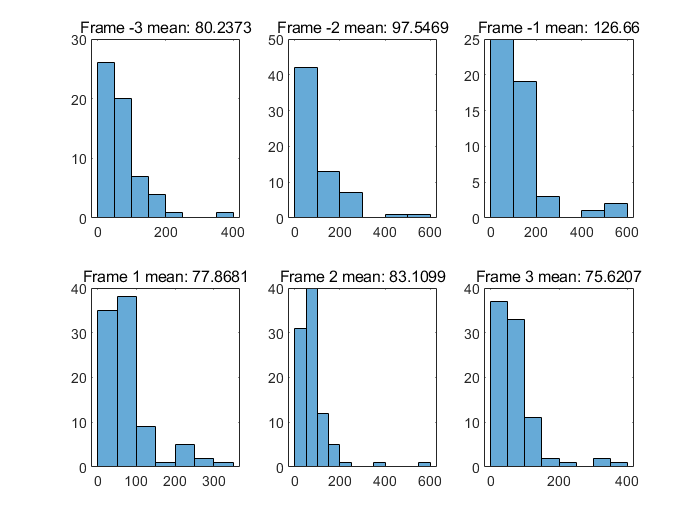

figure(1);
subplot(2,3,1); histogram(l1);  subtitle("Frame -3 mean: "+ mean(l1));    
subplot(2,3,2); histogram(l2);  subtitle("Frame -2 mean: "+ mean(l2));
subplot(2,3,3); histogram(l3);  subtitle("Frame -1 mean: "+ mean(l3));
subplot(2,3,4); histogram(l4);  subtitle("Frame 1 mean: "+ mean(l4));
subplot(2,3,5); histogram(l5);  subtitle("Frame 2 mean: "+ mean(l5)); 
subplot(2,3,6); histogram(l6);  subtitle("Frame 3 mean: "+ mean(l6)); 


L = {l1,l2,l3,l4,l5,l6}

L = 1×6 cell array
    {[135 81 57 93 45 48 90 81 57 36 72 60 81 33 75 87 180 48 66 141 42 183 81 33 72 120 33 42 33 129 42 87 48 42 48 45 33 45 231 360 36 54 174 147 189 114 54 63 48 42 30 147 42 42 33 39 57 78 30]}    {[111 63 120 33 51 30 39 36 108 51 33 108 60 81 36 42 42 48 111 249 69 132 39 81 45 60 33 42 36 33 45 30 111 51 216 105 60 117 153 33 63 213 39 36 60 51 36 57 105 246 297 108 219 36 240 417 45 561 42 141 66 96 81 45]}    {[90 72 33 177 105 42 75 102 144 45 51 45 111 42 57 81 519 123 57 255 267 168 141 573 192 114 90 63 150 402 141 129 39 180 45 174 141 162 36 54 54 69 126 108 45 216 75 33 66 54]}    {[117 42 51 36 30 75 51 51 36 81 108 54 60 30 117 48 36 33 45 30 51 42 39 54 72 234 54 180 93 54 72 39 60 57 54 72 36 36 39 33 72 36 48 45 108 141 30 45 312 279 135 219 90 54 204 231 270 243 42 81 48 54 69 36 96 60 30 39 45 33 30 87 111 72 84 51 36 69 84 48 57 51 138 69 42 33 108 54 48 57 60]}    {[213 33 48 87 99 84 39 93 75 75 60 45 42 600 51 57 51 45 33 99 54 93 198 153 1

### How does the number of genes stated above compare with the number of ORFs you find – explain your result. 

In the description we are given that for this sequence we are expected to find 13 coding genes and 24 non-coding ones.

Therefore it is expected that the number of bases being counted as part of ORFs just found above must be proportional to the 13/37 of the total sequence, and hence the remaining part proportional to the 24/37 of the whole sequence.

Now, for each reading frame, 

- sum all lengths of all found ORFs 

- evaluate ratio R1 (coding genes bases) / (all bases)

- evaluate ratio R2 (remaining bases) / (all bases)

- check how R1 compares to 13/37

- check how R2 compares to 14/37


EXPECTED_CODING_RATIO     = 13/37

EXPECTED_CODING_RATIO = 0.3514

EXPECTED_NON_CODING_RATIO = 24/37

EXPECTED_NON_CODING_RATIO = 0.6486

disp(" ")


for i = 1 : length(L)                                % for each frame:
    j = i; if i <= 3; j = j-1; end; frame = j-3      % print frame index
    coding_bases_sum = sum(L{(i)});                  % count coding genes bases
    ACTUAL_CODING_RATIO = coding_bases_sum / len     % coding bases ratio   
    remaining = len-coding_bases_sum;                % count remaining genes bases
    ACTUAL_NON_CODING_RATIO = remaining / len        % non coding bases ratio
    disp(" ")
end

frame = -3

ACTUAL_CODING_RATIO = 0.2858

ACTUAL_NON_CODING_RATIO = 0.7142

frame = -2

ACTUAL_CODING_RATIO = 0.3769

ACTUAL_NON_CODING_RATIO = 0.6231

frame = -1

ACTUAL_CODING_RATIO = 0.3823

ACTUAL_NON_CODING_RATIO = 0.6177

frame = 1

ACTUAL_CODING_RATIO = 0.4278

ACTUAL_NON_CODING_RATIO = 0.5722

frame = 2

ACTUAL_CODING_RATIO = 0.4566

ACTUAL_NON_CODING_RATIO = 0.5434

frame = 3

ACTUAL_CODING_RATIO = 0.3972

ACTUAL_NON_CODING_RATIO = 0.6028

We can definitely assume ratios from frame -2 are highly correlated with the expected ones,

indeed we can see frame -2 has ratios [0.3769, 0.6231] which, considered the length of the sequence, it is accurate enough to assume these ORFs evaluated are very likely to be in the expected configuration, therefore not only we might assume the ORFs have properly been analysed but also that reading them from these frames (-2, -1, 3) gives much more accuracy than other frames, even though the other ones (-3,1,2) are not 'extremely off' the expectations.

## Part 2

### Using what you have learnt above explore the neanderthal mitochondrial genome and find at least one *interesting* feature. Explain what you have found and what makes it interesting.

Count frequencies of bases

count_freq = basecount(neanderthal)

count_freq = struct with fields:
    A: 5107
    C: 5174
    G: 2180
    T: 4104


Analyse dimers 

[dimers, P] = dimercount(neanderthal)

dimers = struct with fields:
    AA: 1589
    AC: 1490
    AG: 799
    AT: 1229
    CA: 1533
    CC: 1769
    CG: 431
    CT: 1441
    GA: 611
    GC: 718
    GG: 432
    GT: 418
    TA: 1374
    TC: 1197
    TG: 517
    TT: 1016


P =     0.0959    0.0900    0.0482    0.0742
    0.0926    0.1068    0.0260    0.0870
    0.0369    0.0433    0.0261    0.0252
    0.0830    0.0723    0.0312    0.0613


% dimers is a struct with Dimers paired with their occurencies
% P is a vector with all dimers probabilities


Convert data types and extract names

cfn = fieldnames(count_freq);
cfc = struct2cell(count_freq);
P = reshape(P,[1,16]);
n = fieldnames(dimers);
names = cell2mat(n);

Loop through dimers and evaluate odds ratio

for k=1:length(names)           % for every dimer
    dimer = names(k,:)          % dimer character array with symbols of bases
    dimer_freq = P(k);          % dimer observed frequency 
    den = 1;                    % denominator
    for base = 1:length(dimer)  % loop every base in the dimer (they are only 2)
        b = dimer(base);        % single base character symbol
        fx= count_freq.(b)/len; % single base expected frequency
        den = den * fx;         % product of expected frequencies
    end

    odds_ratio = dimer_freq / den
end

dimer = 'AA'

odds_ratio = 1.0093

dimer = 'AC'

odds_ratio = 0.9611

dimer = 'AG'

odds_ratio = 0.9092

dimer = 'AT'

odds_ratio = 1.0860

dimer = 'CA'

odds_ratio = 0.9341

dimer = 'CC'

odds_ratio = 1.0947

dimer = 'CG'

odds_ratio = 1.0545

dimer = 'CT'

odds_ratio = 0.9339

dimer = 'GA'

odds_ratio = 1.1889

dimer = 'GC'

odds_ratio = 0.6330

dimer = 'GG'

odds_ratio = 1.5059

dimer = 'GT'

odds_ratio = 0.9573

dimer = 'TA'

odds_ratio = 0.9714

dimer = 'TC'

odds_ratio = 1.1242

dimer = 'TG'

odds_ratio = 0.7740

dimer = 'TT'

odds_ratio = 0.9993

We can now take a look at the odds ratio and we can clearly see a weird behaviour of the GG and GC dimers, they are indeed quite off the odds ratio, which means one base G is way more likely to appear after another G base rather than a base C being after a G.

We can consider these values (GG 1.5059 and GC 0.6330) fairly off the expected threshold, due also to the lenght of the sequence (16565) which is fairly reasonable length for a gene sequence, and hence making those values be quite a bit out of expectations range. Sounds interesting!